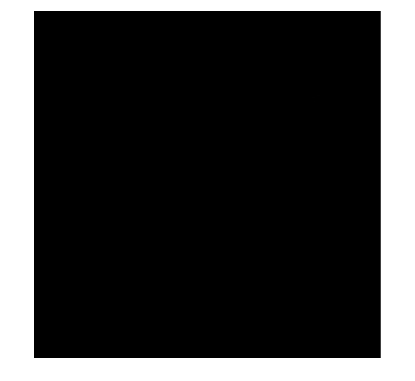

%% Author: Rhea Kaul
%% Date created: 10th June 2023
%% Date of last edit : 24th June 2023

    file = uigetdir;
    image = im2double(squashImages(file, 1)); %% Get image
    imshow(image);

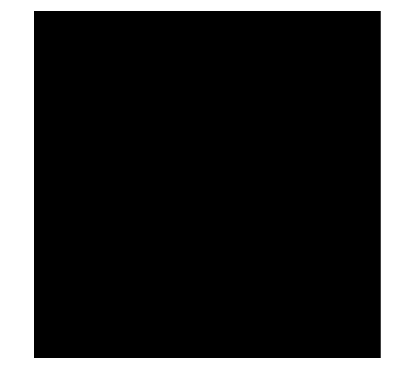


    wdisk = fspecial('disk', 20); %% Disk filter, radius of 3 (20 for the other rez)
    diskImage = imfilter(imadjust(image, [0.05 1.0]),...
        wdisk, 'symmetric'); %% Apply filter, adjust image to remove noise
    imshow(diskImage);


    mask = imfill(diskImage, 'holes'); %% Fill holes to get cell data
    imshow(mask);


    mask = bwareaopen(mask, 2); %% Remove noise
    imshow(mask);


    connectedComp = bwconncomp(mask); %% Find connected components
    data = regionprops(connectedComp, 'Area', 'Centroid', 'PixelList'); %% Get data

    [~,index] = max([data.Area]); %% Define the cell as the largest object in the field
    centroid = data(index).Centroid; %% Get Centroid of largest object (cell)

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.

    x = centroid(1, 1); %% Get x coordinate of centroid
    y = centroid(1, 2); %% Get y coordinate of centroid
    
    coordinates = [data(index).PixelList(:, 1),...
    data(index).PixelList(:, 2)]; %% XY coordinates

    [ysize, xsize] = size(image); %% Get image size 
    mask = zeros(ysize, xsize); %% Create a blank mask

    for j = 1:length(coordinates)
        mask(coordinates(j, 2), coordinates(j, 1)) = 1; %% Create a mask
    end

    maskedimage = image.*mask;
    imshow(maskedimage);

    outline = bwtraceboundary(mask, [coordinates(1, 2), coordinates(1, 1)], 'S'); %% Trace outline
    plot(outline(:,2),outline(:,1),'g','LineWidth',2)
    
    distances = zeros(length(outline), 1); %% Create vector to hold the distances
    
    for k = 1: length(outline)
        distances(k) = sqrt((outline(k, 2) + x) ^ 2 + (outline(k, 1) + y) ^ 2); %% Find the distance between centroid and outside
    end
    
    figure(2)
    plot((1 : length(distances)), distances); %% Make a plot for special effects
    
    [~, ~, widths, prominences] = findpeaks(distances,'MinPeakDistance',50); %% Get the width and height of the peaks in the data
    %% 10 for lower rez and 50 for higher
    

    ProtrusionHeights = zeros(length(prominences), 1); %% Make space
    ProtrusionWidths = zeros(length(widths), 1); %% For the generated
    ProtrusionARs = zeros(length(prominences), 1); %% Protrusion data for this image
    
    for m = 1 : length(prominences)
        ProtrusionHeights(m) = prominences(m); %% Record heights of protrusions
        ProtrusionWidths(m) = widths(m); %% Record widths of protrusions
        ProtrusionARs(m) = prominences(m) / widths(m); %% Calculate the AR
    end
